# Matlab implementation of the QDSI test (Mainhard et al. 2009)

The function **QSDI** (Questionnaire on Supervisor–Doctoral Student Interaction) is inspired by the model developed by **Mainhard et al. (2009)**, which builds on the **interpersonal behavior framework.** This model conceptualizes the relationship between doctoral supervisors and their students in terms of interpersonal dynamics, focusing on two dimensions: **Influence** (dominance–submission) and **Proximity** (cooperation–opposition). These dimensions describe the social-emotional aspects of supervision and are widely recognized as key factors influencing PhD satisfaction, progress, and supervisory effectiveness.

The objective of the `QSDI` function is to process and analyze questionnaire data from both supervisor and doctoral student perspectives, summarizing their responses into eight interactional categories:**'DC','CD','CS','SC','SO','OS','OD','DO'**.

Each code represents a segment of the interpersonal circle, capturing combinations of **Dominance (D)**, **Submission (S)**, **Cooperation (C)**, and **Opposition (O)**. Together, these categories provide a structured way to visualize and compare how each party perceives their relationship across multiple relational styles (e.g., directive, understanding, or oppositional behaviors).

From a practical standpoint, the QSDI function enables quantitative analysis of supervisor–student interactions and provides a foundation for visual feedback tools, self-assessment, and research on doctoral supervision quality. 

## Read the questionnaires and call the function QSDI

clearvars;close all;clc;
rng(1)
if ~exist([pwd,'/figures'],'dir'), mkdir([pwd,'/figures']); end

% Define 10 supervisor–student name pairs
names = {
    'Bobby_Bob',      'Franky_Frank';
    'Alice_Anderson', 'Sally_Smith';
    'Carlos_Cruz',    'Lina_Lopez';
    'David_Doe',      'Nina_Nash';
    'Ethan_Evans',    'Mona_Mills';
    'Fiona_Frost',    'Oscar_Ortiz';
    'Gina_Grey',      'Paul_Perez';
    'Henry_Holt',     'Rita_Reed';
    'Ian_Ives',       'Tina_Turner';
    'Jack_Jones',     'Una_Underwood';
    };


clear S
tic
for ii= 1:size(names,1)
    supervisor = ['./QSDI_Test_Data/qsdi_',names{ii,1},'.csv'];
    student = ['./QSDI_Test_Data/qsdi_',names{ii,2},'.csv'];
    [S{ii},scale_labels] = QSDI(supervisor, student, 'randomize',true);
end
toc

Elapsed time is 0.546481 seconds.


## Visualize the answer using a spider plot

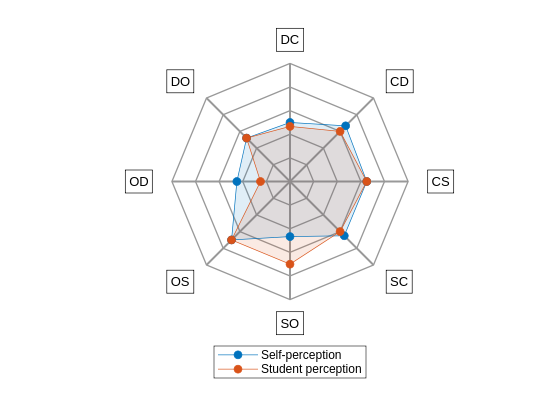

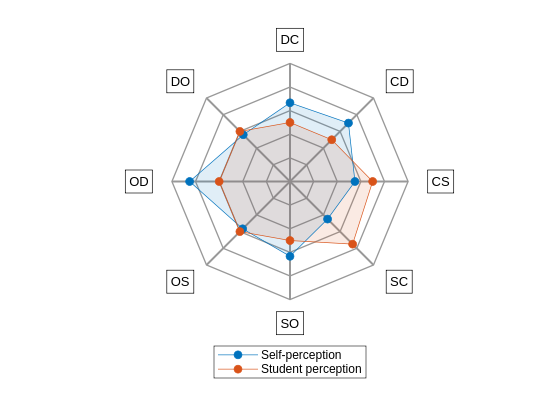

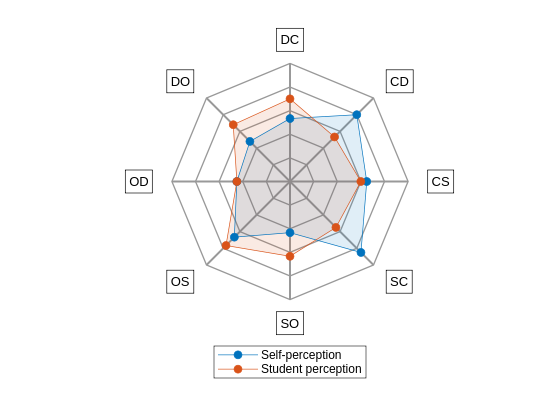

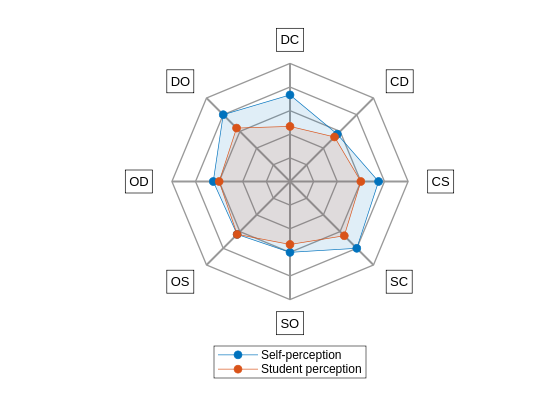

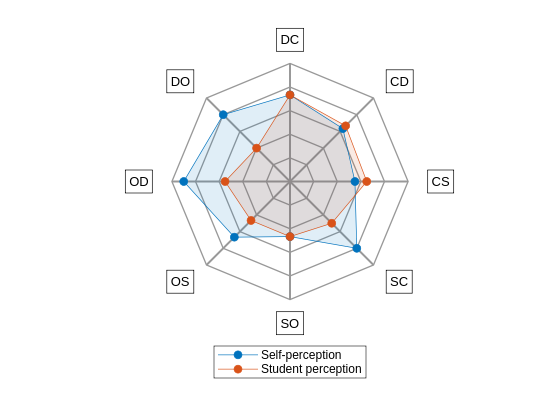

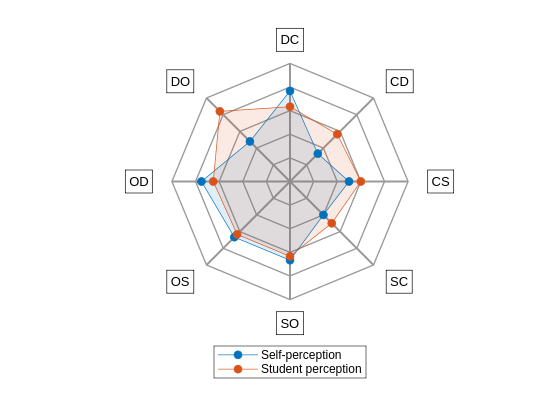

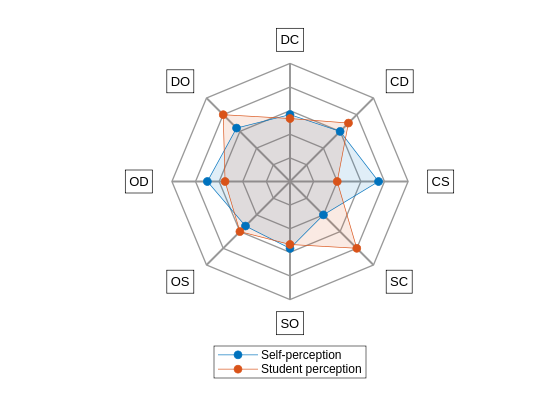

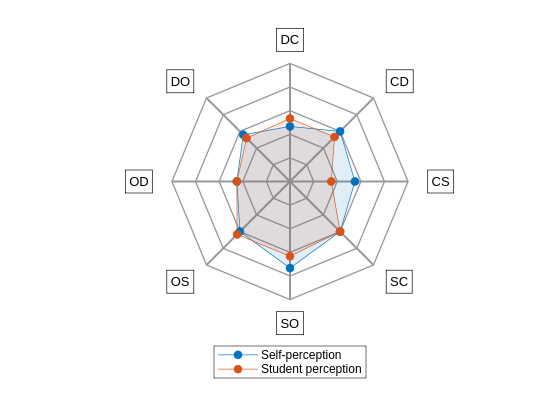

axes_limits = [ones(1,8)*1; ones(1,8)*5];
clf;close all;

for ii= 1:size(names,1)
    figure('Color','w');
    spider_plot_R2019b(S{ii}, ...
        'AxesLabels', scale_labels, ...
        'AxesInterval', 4, ...
        'AxesTickLabels', {'','','','',''},...
        'AxesPrecision', 1, ...
        'AxesLimits', axes_limits, ...
        'FillOption', 'on', ...
        'FillTransparency', 0.12, ...
        'LineWidth', 0.5);
    legend({'Self-perception','Student perception'}, 'Location','southoutside');
    exportgraphics(gcf,['./figures/spiderPlot_',names{ii,1},'_',names{ii,2},'.pdf'])
end

## Interpretation

Let's consider the first par of supervisor-supervisee (case 1)

  figure('Color','w');
    spider_plot_R2019b(S{ii}, ...
        'AxesLabels', scale_labels, ...
        'AxesInterval', 4, ...
        'AxesTickLabels', {'','','','',''},...
        'AxesPrecision', 1, ...
        'AxesLimits', axes_limits, ...
        'FillOption', 'on', ...
        'FillTransparency', 0.12, ...
        'LineWidth', 0.5);
    legend({'Self-perception','Student perception'}, 'Location','southoutside');

**CD** reflects the helping/friendly scale. Both supervisor and student see the supervisor as generally friendly and supportive.

**DC** represents leadership. Both student (3.7) and supervisor (3.0) agree that the supervisor shows clear, structured leadership, with the student perceiving slightly stronger direction and confidence

**DO** represents strictness. Both agree that the supervisor is moderately strict (3.2 vs 2.8), maintaining expectations and standards without excessive rigidity.

**OD** represents admonishing. Both perceive the supervisor as only occasionally critical (3.25 vs 2.75), indicating feedback that is demanding but not hostile

**OS** represents dissatisfaction. The supervisor feels satisfied (2.0), while the student senses notable dissatisfaction (3.7), suggesting a communication gap in how approval or criticism is conveyed.

**SO** represents uncertainty. Both view the supervisor as somewhat uncertain (3.0 vs 3.5), possibly eflecting occasional ambiguity or mixed signals during discussions. 

**SC** represents the student’s responsibility/freedom. Both agree that autonomy is moderate (3.0 vs 2.5), showing a balance between independence and supervision, though the supervisor perceives granting slightly more freedom.

**CS** represents understanding. Both see the supervisor as understanding and attentive (4.0 vs 3.25), with generally positive and empathetic interactions, though the supervisor rates this more favorably.